clear all; clc;

x0 = 1e-3; % initial position
vx0 = 1e-3; % initial velocity along x

d = 50e-6; % diameter

EPS0 = 8.85e-12; 
surface_tension = 0.0728;
Rl = 8*pi*sqrt(EPS0*surface_tension*(d/2)^3); % Rayleigh limit
q = 0.3*Rl; % droplet charge

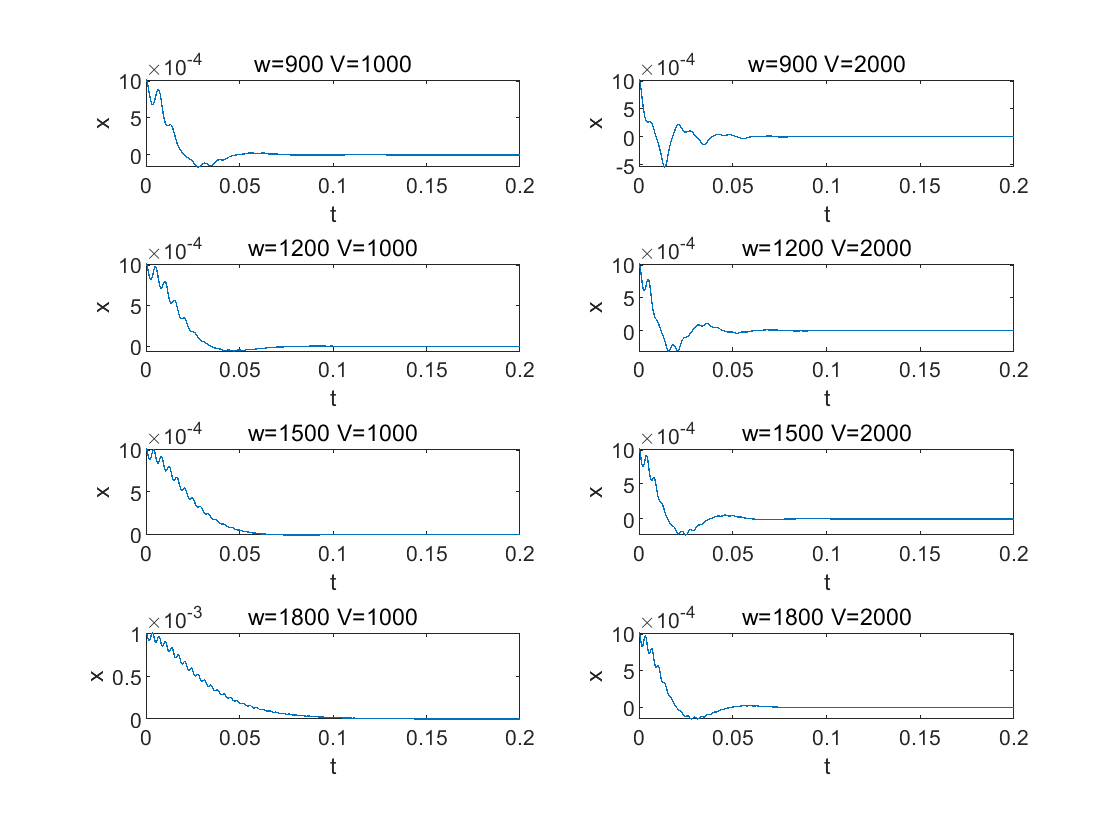

% 1
figure;
k = 1;
for w = 900:300:1800
    for V = [1000 2000]
        [t, x] = ode45(@(t,x) fun1(t,x,w,V,q), [0 0.2], [x0 vx0]);
        subplot(4,2,k);
        plot(t, x(:,1));
        title("w="+int2str(w)+" "+"V="+int2str(V));
        xlabel('t'); ylabel('x');
        k = k + 1;
    end
end

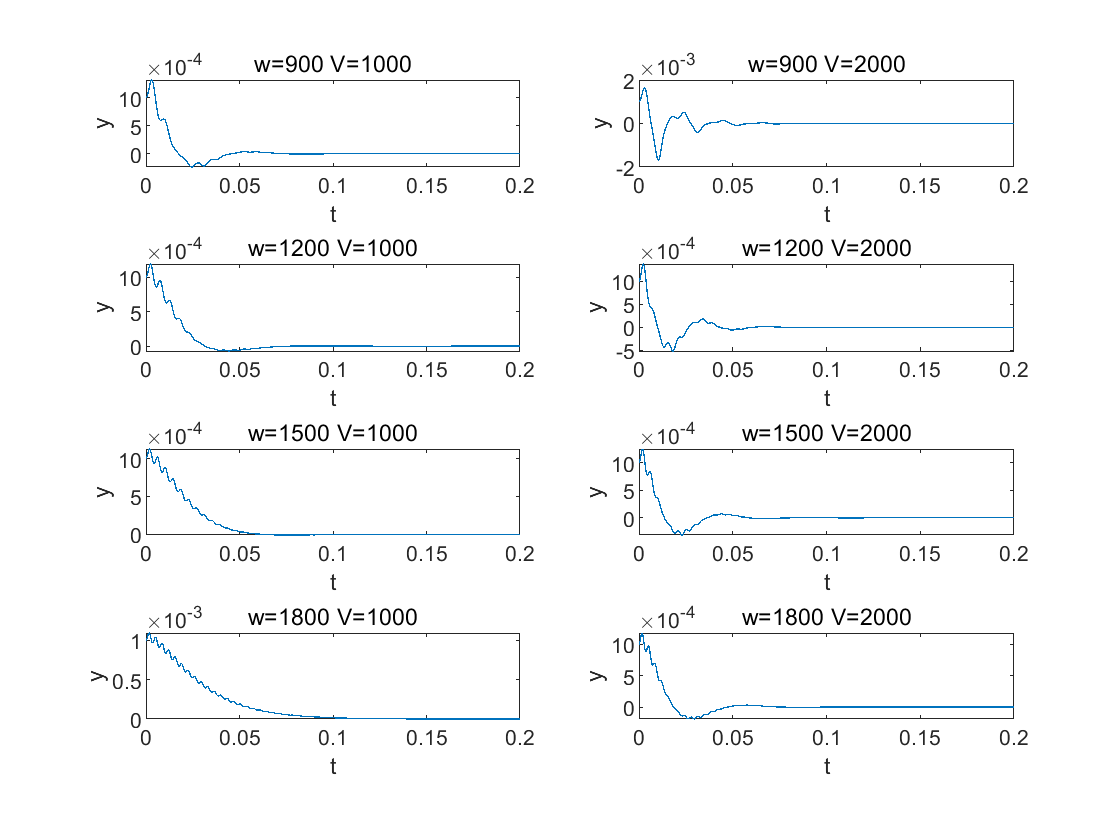

figure;
k = 1;
for w = 900:300:1800
    for V = [1000 2000]
        [t, y] = ode45(@(t,y) fun2(t,y,w,V,q), [0 0.2], [x0 vx0]);
        subplot(4,2,k);
        plot(t, y(:,1));
        title("w="+int2str(w)+" "+"V="+int2str(V));
        xlabel('t'); ylabel('y');
        k = k + 1;
    end
end

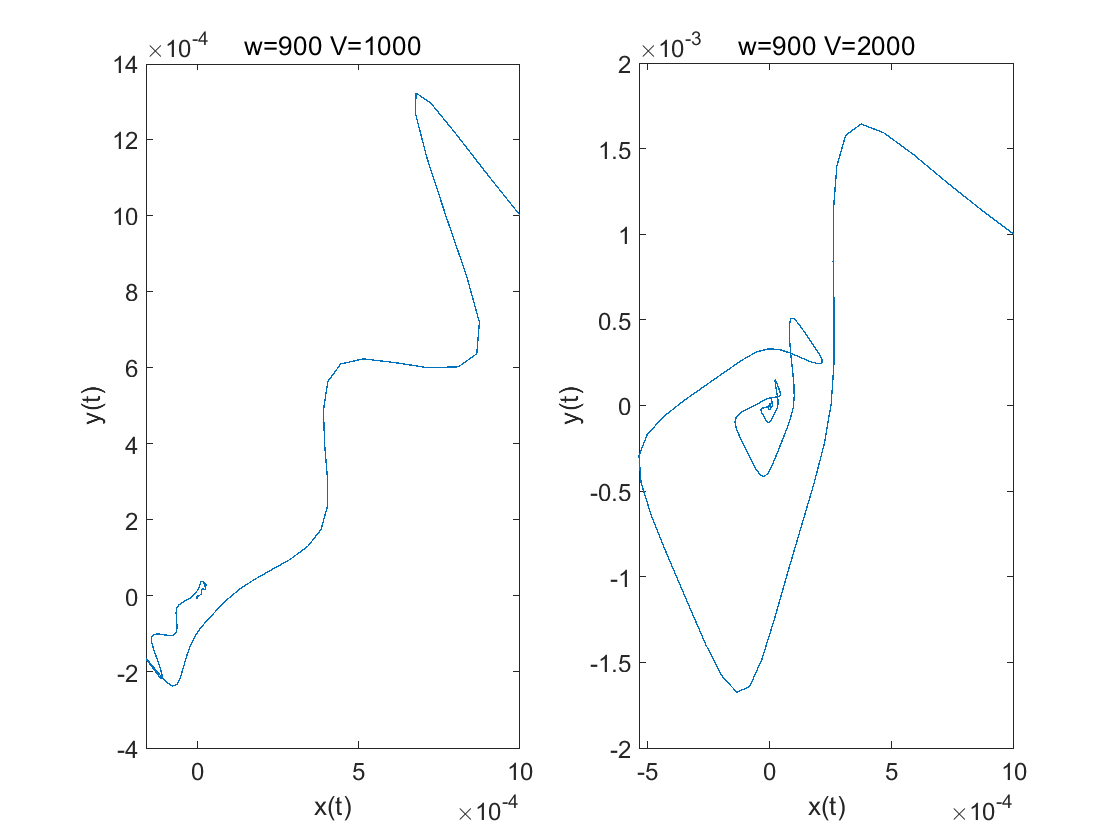

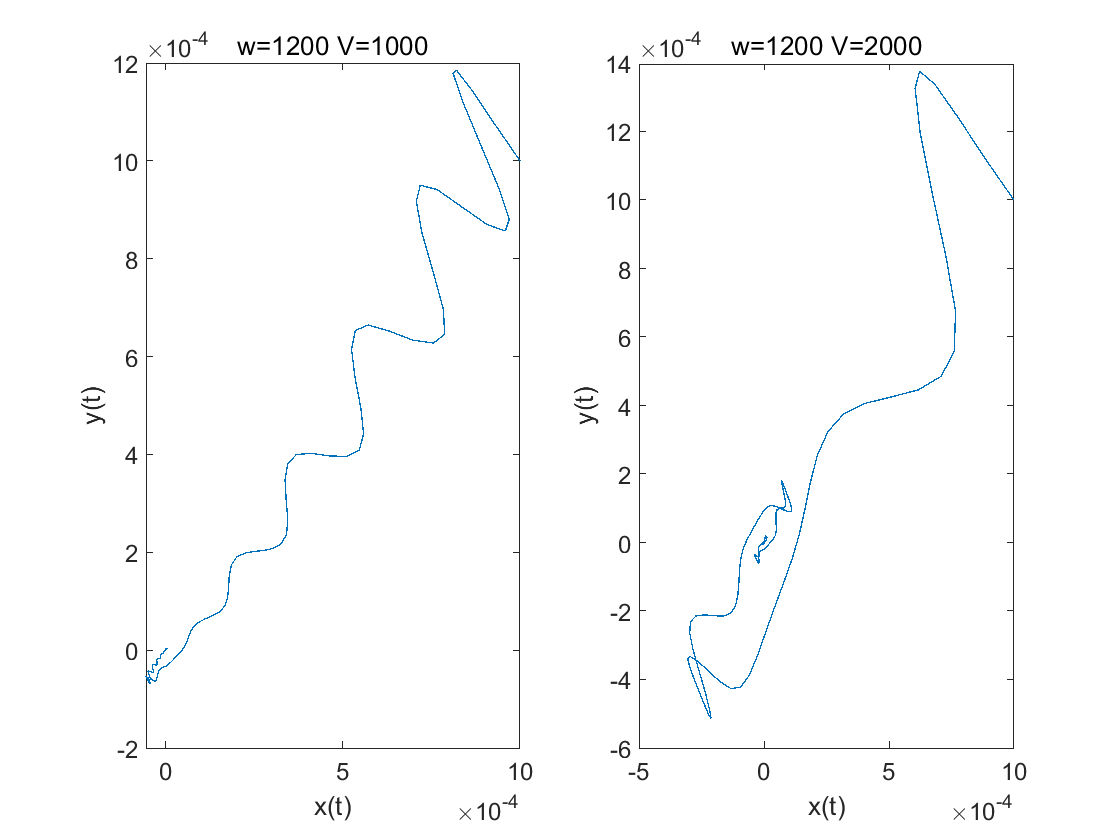

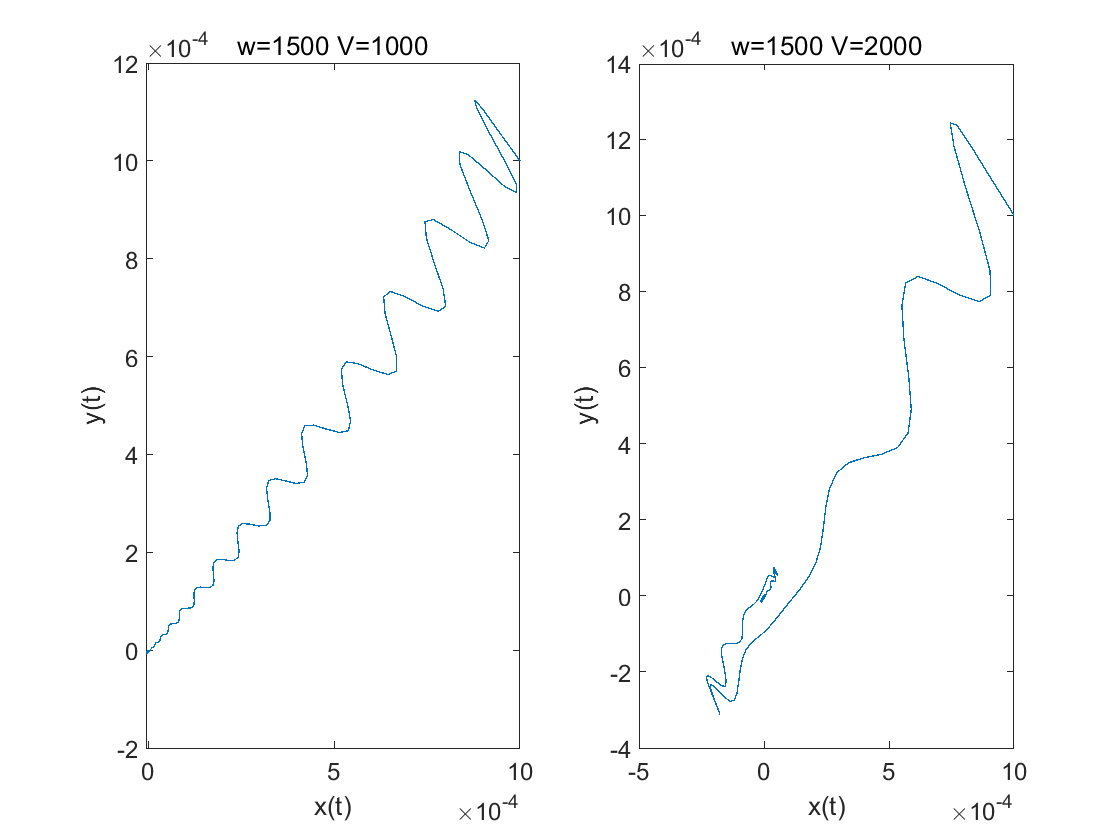

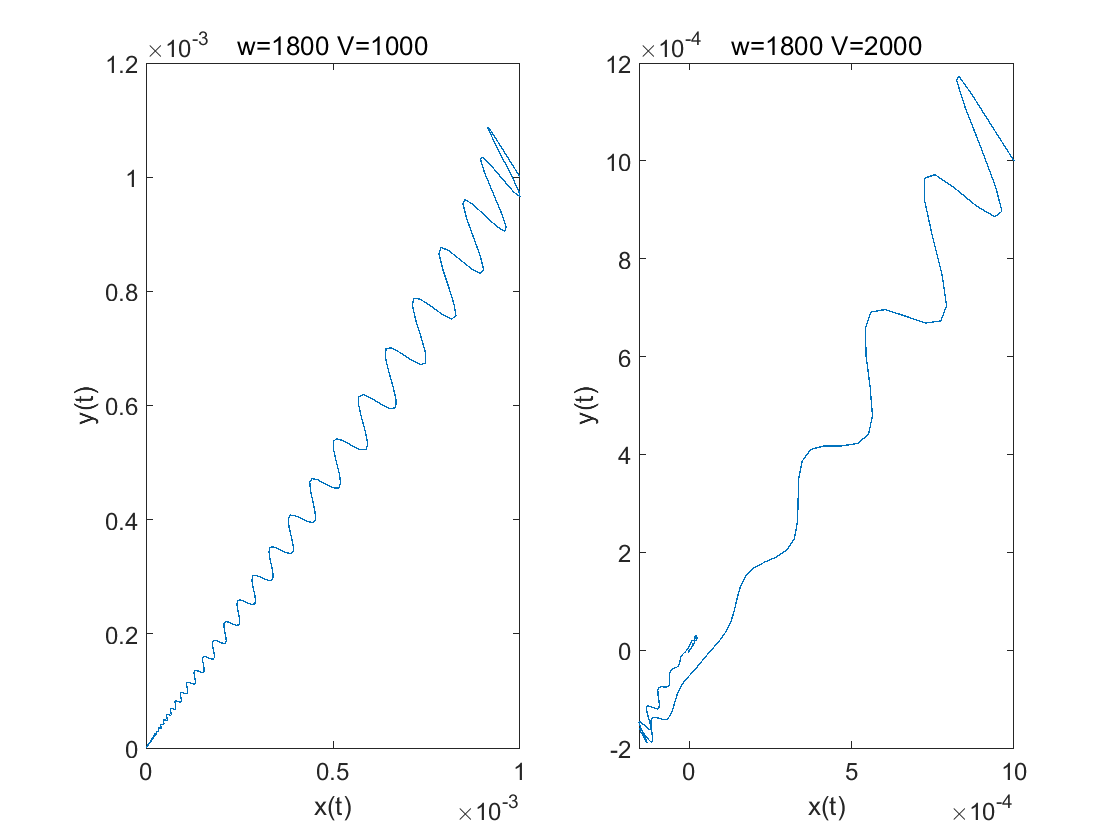

% 2
k = 1;
for w = 900:300:1800
    figure;
    for V = [1000 2000]
        [t1, x] = ode45(@(t,x) fun1(t,x,w,V,q), [0 0.2], [x0 vx0]);
        [t2, y] = ode45(@(t,y) fun2(t,y,w,V,q), [0 0.2], [x0 vx0]);
        t = linspace(0, 0.5, size(t1, 1) * 2);                   
        xvals = interp1(t1, x(:, 1), t);                        
        yvals = interp1(t2, y(:, 1), t);   
        subplot(1,2,k);
        plot(xvals, yvals);
        title("w="+int2str(w)+" "+"V="+int2str(V));
        xlabel('x(t)'); ylabel('y(t)');
        k = k + 1;
    end
    k = 1;
end

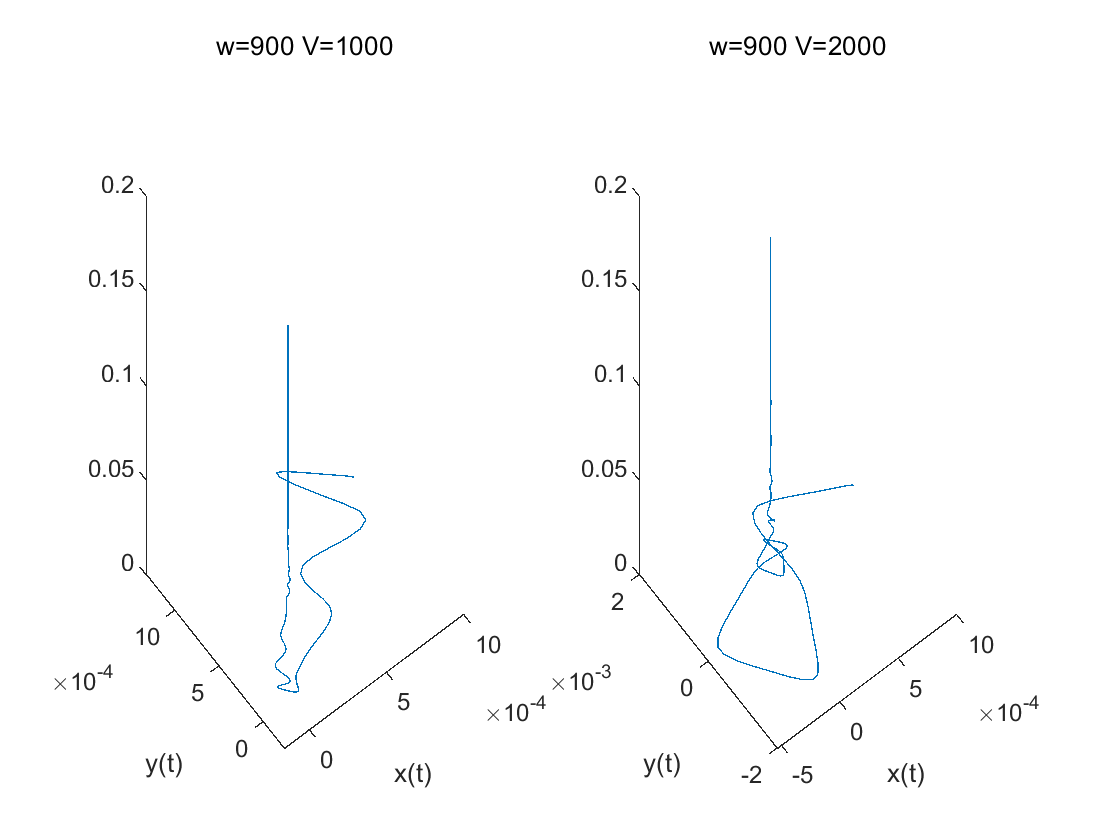

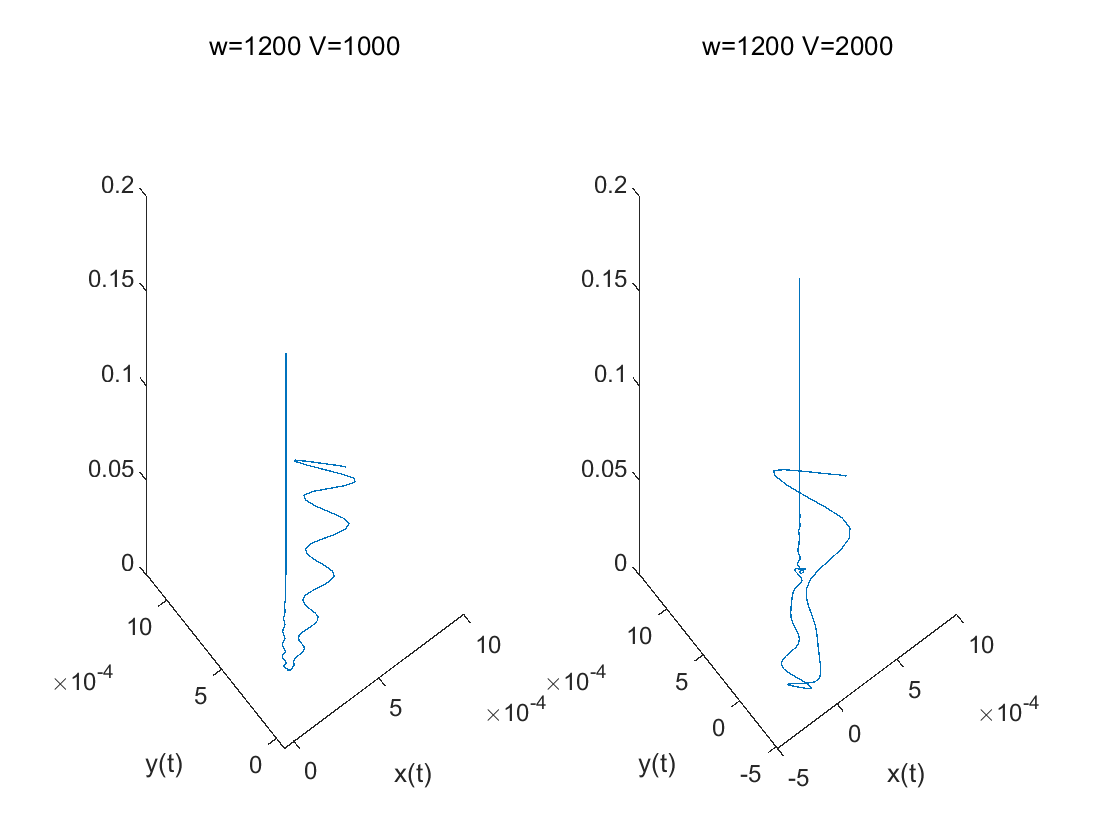

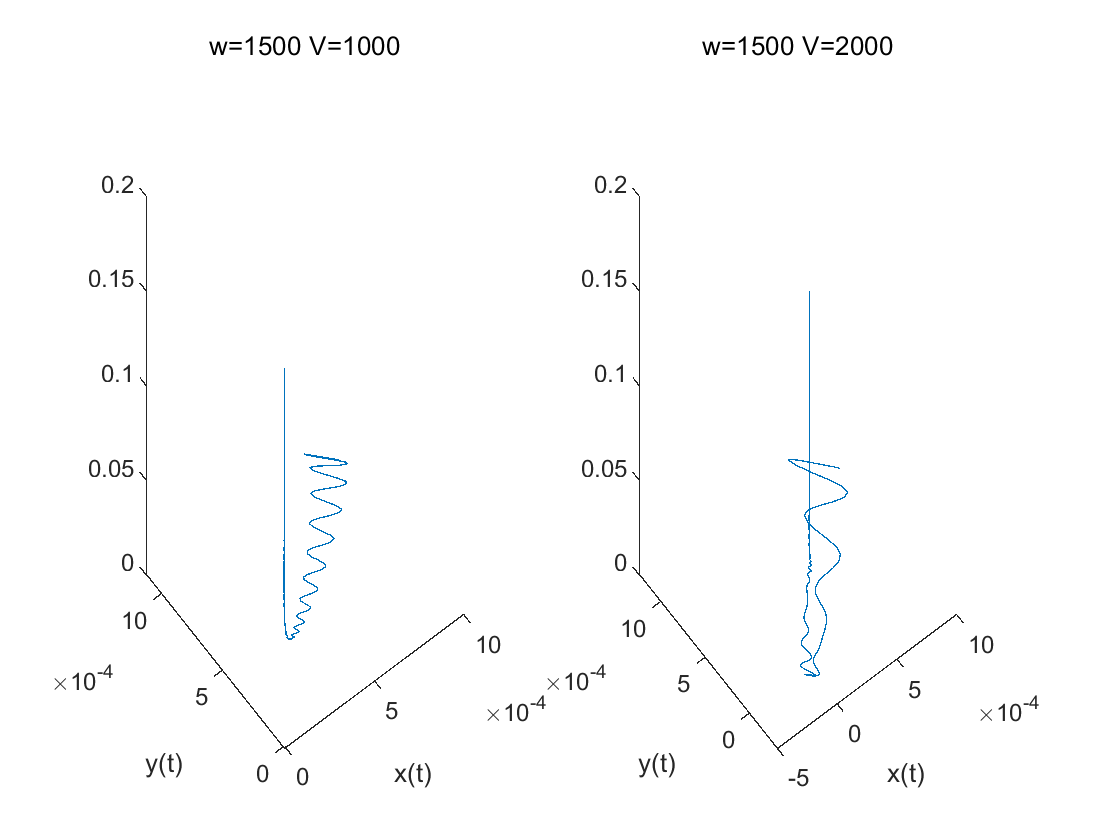

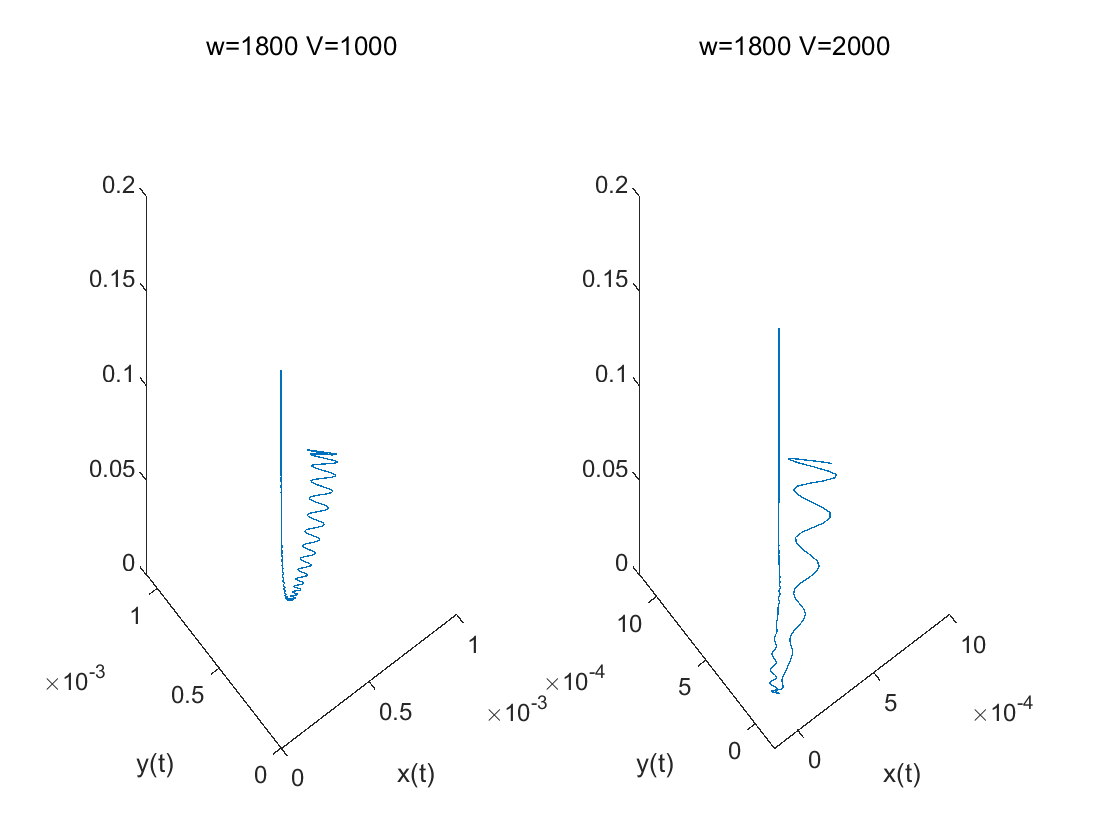

k = 1;
for w = 900:300:1800
    figure;
    for V = [1000 2000]
        [t1, x] = ode45(@(t,x) fun1(t,x,w,V,q), [0 0.2], [x0 vx0]);
        [t2, y] = ode45(@(t,y) fun2(t,y,w,V,q), [0 0.2], [x0 vx0]);
        t = linspace(0, 0.5, size(t1, 1) * 2);                   
        xvals = interp1(t1, x(:, 1), t);                        
        yvals = interp1(t2, y(:, 1), t);   
        subplot(1,2,k);
        plot3(xvals, yvals,t);
        title("w="+int2str(w)+" "+"V="+int2str(V));
        xlabel('x(t)'); ylabel('y(t)');
        k = k + 1;
    end
    k = 1;
end

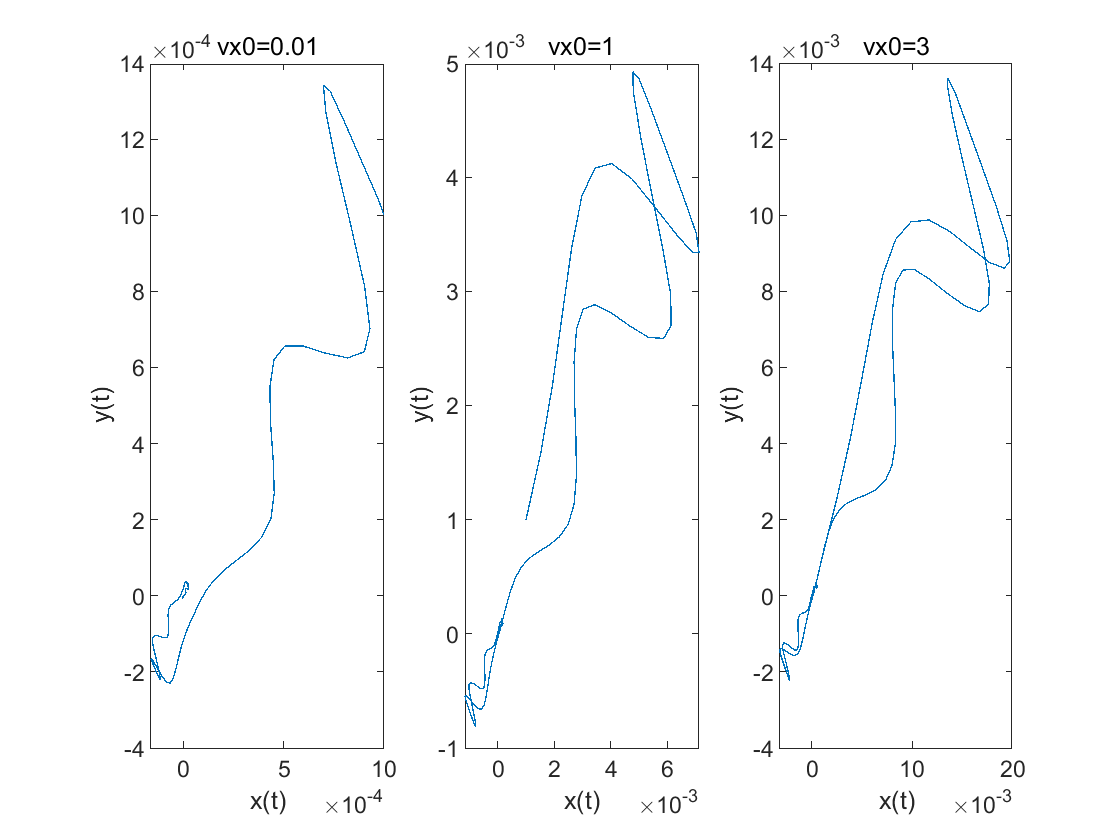

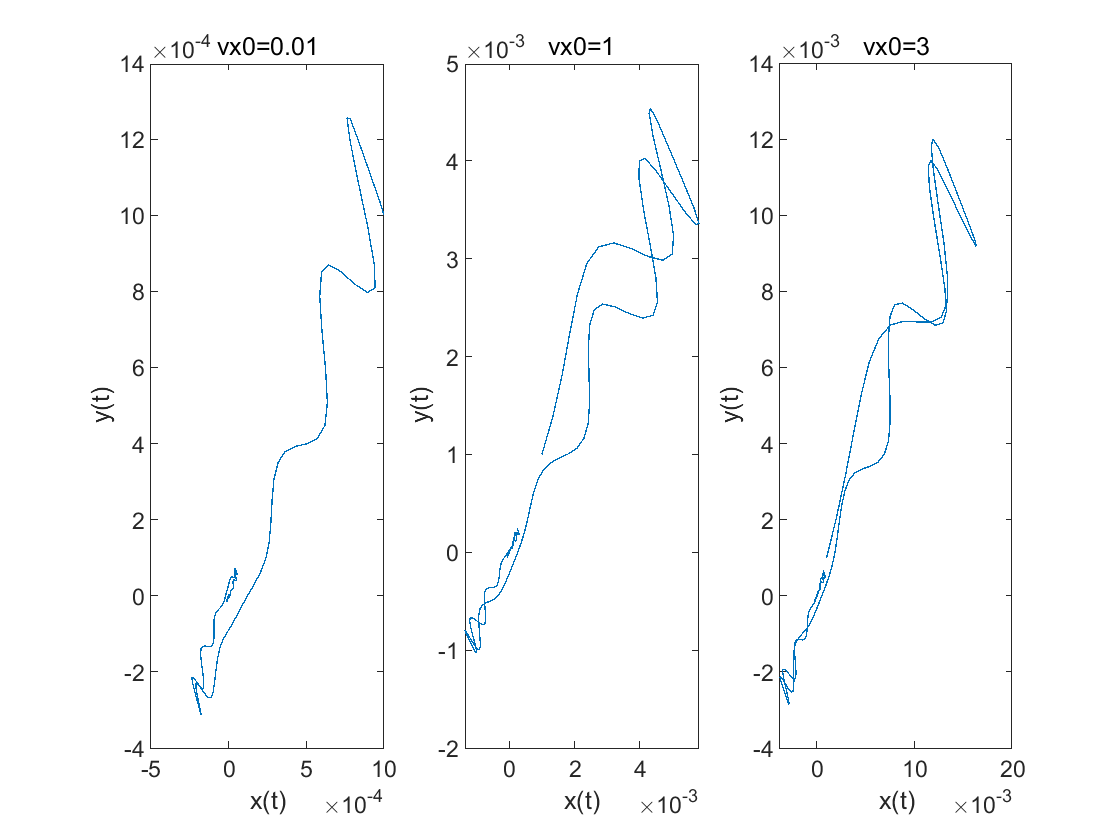

% 3
k = 1;
x0 = 1e-3;
vx0 = [0.01 1 3];
w = [900 1500];
V = [1000 2000];
for j = 1:2
    figure
    for i = 1:3
        [t1, x] = ode45(@(t,x) fun1(t,x,w(j),V(j),q), [0 0.2], [x0 vx0(i)]);
        [t2, y] = ode45(@(t,y) fun2(t,y,w(j),V(j),q), [0 0.2], [x0 vx0(i)]);
        t = linspace(0, 0.5, size(t1, 1) * 2);                   
        xvals = interp1(t1, x(:, 1), t);    
        yvals = interp1(t2, y(:, 1), t);  
        subplot(1,3,k);
        plot(xvals, yvals);
        title("vx0="+num2str(vx0(i)));
        xlabel('x(t)'); ylabel('y(t)');
        k = k + 1;
    end
    k = 1;
end

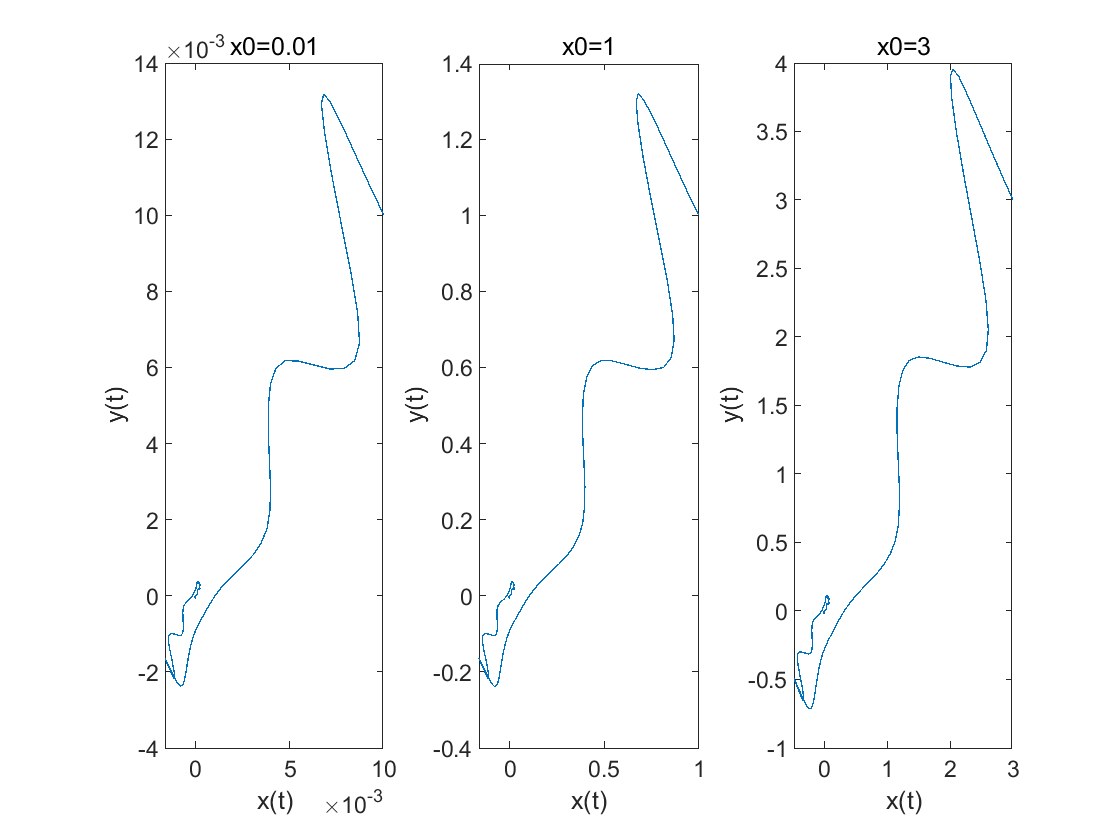

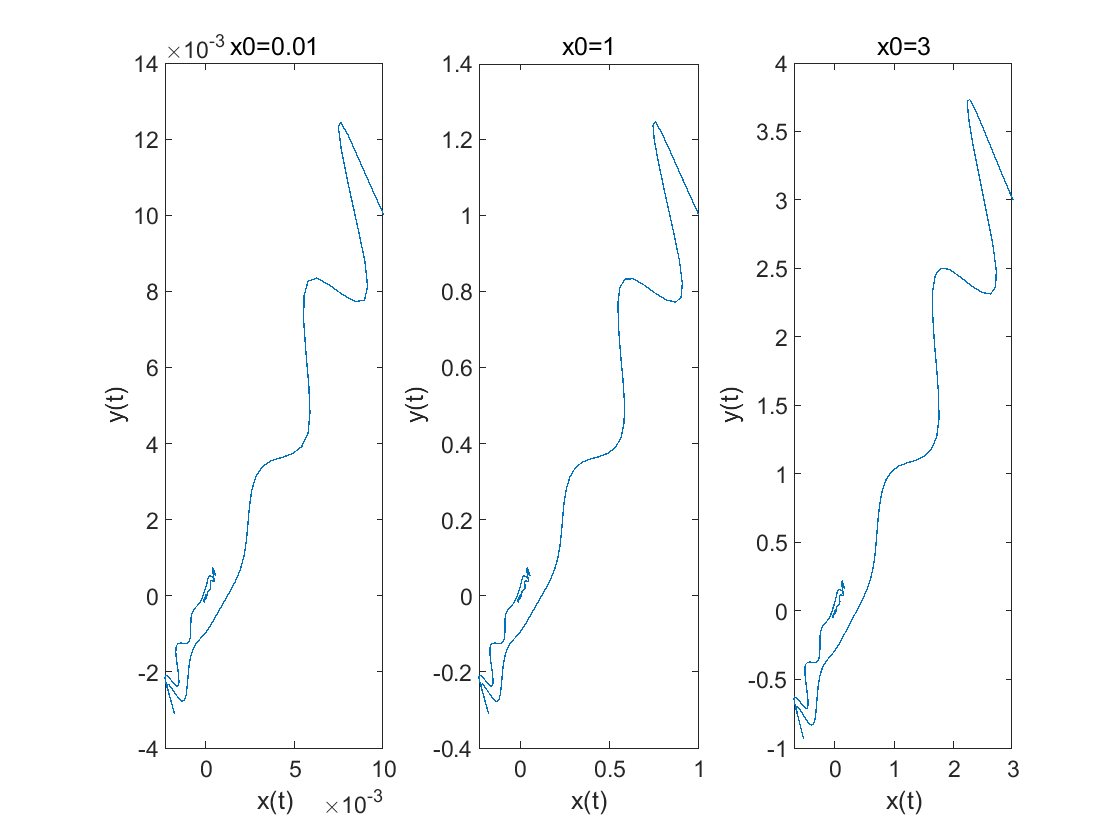

k = 1;
x0 = [0.01 1 3];
vx0 = 1e-3;
w = [900 1500];
V = [1000 2000];
for j = 1:2
    figure
    for i = 1:3
        [t1, x] = ode45(@(t,x) fun1(t,x,w(j),V(j),q), [0 0.2], [x0(i) vx0]);
        [t2, y] = ode45(@(t,y) fun2(t,y,w(j),V(j),q), [0 0.2], [x0(i) vx0]);
        t = linspace(0, 0.5, size(t1, 1) * 2);                   
        xvals = interp1(t1, x(:, 1), t);    
        yvals = interp1(t2, y(:, 1), t);  
        subplot(1,3,k);
        plot(xvals, yvals);
        title("x0="+num2str(x0(i)));
        xlabel('x(t)'); ylabel('y(t)');
        k = k + 1;
    end
    k = 1;
end

## fucntions

function z = fun1(t, x, w, V, q)
r0 = 0.012; % initial distance

d = 50e-6; % diameter
m = 1e3*4/3*pi*(d/2)^3; % mass

Ex = -2*x(1)/r0^2*V*cos(w*t);

ita = 17.9e-6;

z = zeros(2,1);
z(1) = x(2);
z(2) = 1/m*Ex*q-3*pi*ita*d*1/m*x(2);
end

function z = fun2(t, y, w, V, q)
r0 = 0.012; % initial distance

d = 50e-6; % diameter
m = 1e3*4/3*pi*(d/2)^3; % mass

Ey = 2*y(1)/r0^2*V*cos(w*t);

ita = 17.9e-6;

z = zeros(2,1);
z(1) = y(2);
z(2) = 1/m*Ey*q-3*pi*ita*d*1/m*y(2);
end